# Final Project

## System Overview

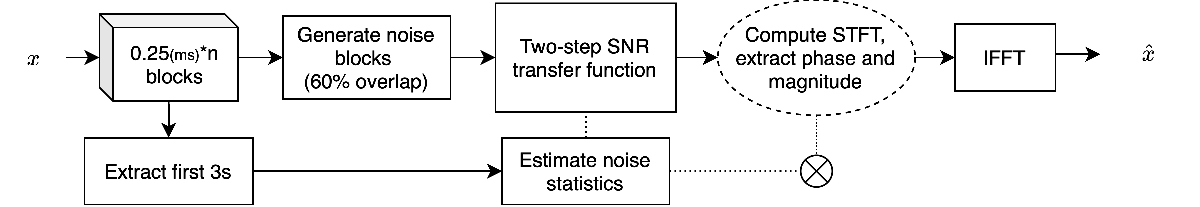

Our methodology is an improvement on the Wiener filter process of noise reduction.The Wiener transfer function is calculated for each block using the two-step approach described in [5], and the filtering process takes place in the frequency domain. We use the transfer function to modify the gain of the magnitude spectrum at each frequency bin and we re-use the phase information from the noisy signal. The blocked frequency domain result is then reconstructed to the time domain. We also implemented a gain control script described by Plapous to avoid circular convolution artifacts.

**Visualization uses Statistics & Machine Learning toolkit. **

## **References**

[1]    A. Zaknich, *Principles of adaptive filters and self-learning systems*. London: Springer London, 2005.

[2]    C. Plapous, C. Marro, Laurent Mauuary, and Pascal Scalart, “A two-step noise reduction technique,” *International Conference on Acoustics, Speech, and Signal Processing*, May 2004, doi: [https://doi.org/10.1109/icassp.2004.1325979](https://doi.org/10.1109/icassp.2004.1325979).

[3]    Pankai Gael, P. Saxena, M. Chandra, and V. K. Gupta, “Comparative analysis of speech enhancement methods,” *Wireless and Optical Communications Networks*, Jul. 2013, doi: [https://doi.org/10.1109/wocn.2013.6616238](https://doi.org/10.1109/wocn.2013.6616238).

[4]    A. Ouardia and F. Merazka , "Denoising of Speech Signal Using Decision Directed Approach", *International Journal of Informatics and Applied Mathematics*, vol. 3, no. 1, pp. 70-83, Jun. 2020

[5]    C. Plapous, C. Marro, and P. Scalart, “Improved Signal-to-Noise Ratio Estimation for Speech Enhancement,” *IEEE Transactions on Audio, Speech and Language Processing*, vol. 14, no. 6, pp. 2098–2108, Nov. 2006, doi: [https://doi.org/10.1109/tasl.2006.872621](https://doi.org/10.1109/tasl.2006.872621).

[6]    P. Scalart and J. V. Filho, “Speech enhancement based on a priori signal to noise estimation,” *1996 IEEE International Conference on Acoustics, Speech, and Signal Processing Conference Proceedings*, doi: [https://doi.org/10.1109/icassp.1996.543199](https://doi.org/10.1109/icassp.1996.543199).

[7]    C. Plapous, C. Marro, and Pascal Scalart, “Speech Enhancement Using Harmonic Regeneration,” *International Conference on Acoustics, Speech, and Signal Processing*, Mar. 2005, doi: [https://doi.org/10.1109/icassp.2005.1415074](https://doi.org/10.1109/icassp.2005.1415074).

[8]    G. Welch and G. Bishop, “An Introduction to the Kalman Filter.” Available: [https://perso.crans.org/club-krobot/doc/kalman.pdf](https://perso.crans.org/club-krobot/doc/kalman.pdf)

[9]    A. Sarafnia and Seyed Ghorshi, “Noise reduction of speech signal using bayesian state-space Kalman filter,” *Asia-Pacific Conference on Communications*, Aug. 2013, doi: [https://doi.org/10.1109/apcc.2013.6766008](https://doi.org/10.1109/apcc.2013.6766008).

[10]    F. G. Encinas, L. A. Silva, A. S. Mendes, G. V. Gonzalez, V. R. Q. Leithardt, and J. F. De Paz Santana, “Singular Spectrum Analysis for Source Separation in Drone-Based Audio Recording,” *IEEE Access*, vol. 9, pp. 43444–43457, 2021, doi: [https://doi.org/10.1109/access.2021.3065775.](https://doi.org/10.1109/access.2021.3065775.)

## Contributions

- Noel Alben: research and implementation

- Joann Ching: evaluation function & bug testing

- Pavan Seshadri: profiler, data loader

- Karthik Varadharajan: description, flowchart, main.mlx 

addpath('src', 'dev')

### Evaluate

%exp_name = 'test';
%data = result_snr;
%filename = './results.txt';
%evaluate(filename, exp_name, result_snr, x, xhat)

devDataPath = "dev";

devDataFolders = ls(devDataPath);
devDataFolders = devDataFolders(4:end, :);

nDevSamples = size(devDataFolders, 1);

initSnr = NaN(nDevSamples, 1);
finalSnr = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i, :), "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i, :), "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);

    estimSig = denoise(noisySig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);

    finalSnr(i) = computeSnr(cleanSig, estimSig);    
end

deltaSnr = finalSnr - initSnr;

fprintf("Input SNR (dB)");

Input SNR (dB)

descStats(initSnr);

min    	median 	mean   	max    	std    
-11.90	1.54	0.43	10.92	6.71


fprintf("Output SNR (dB)");

Output SNR (dB)

descStats(finalSnr);

min    	median 	mean   	max    	std    
-11.44	2.87	2.50	18.74	6.24



fprintf("Change in SNR (dB)");

Change in SNR (dB)

descStats(deltaSnr);

min    	median 	mean   	max    	std    
-3.45	1.66	2.07	9.99	2.45


**Visualize**

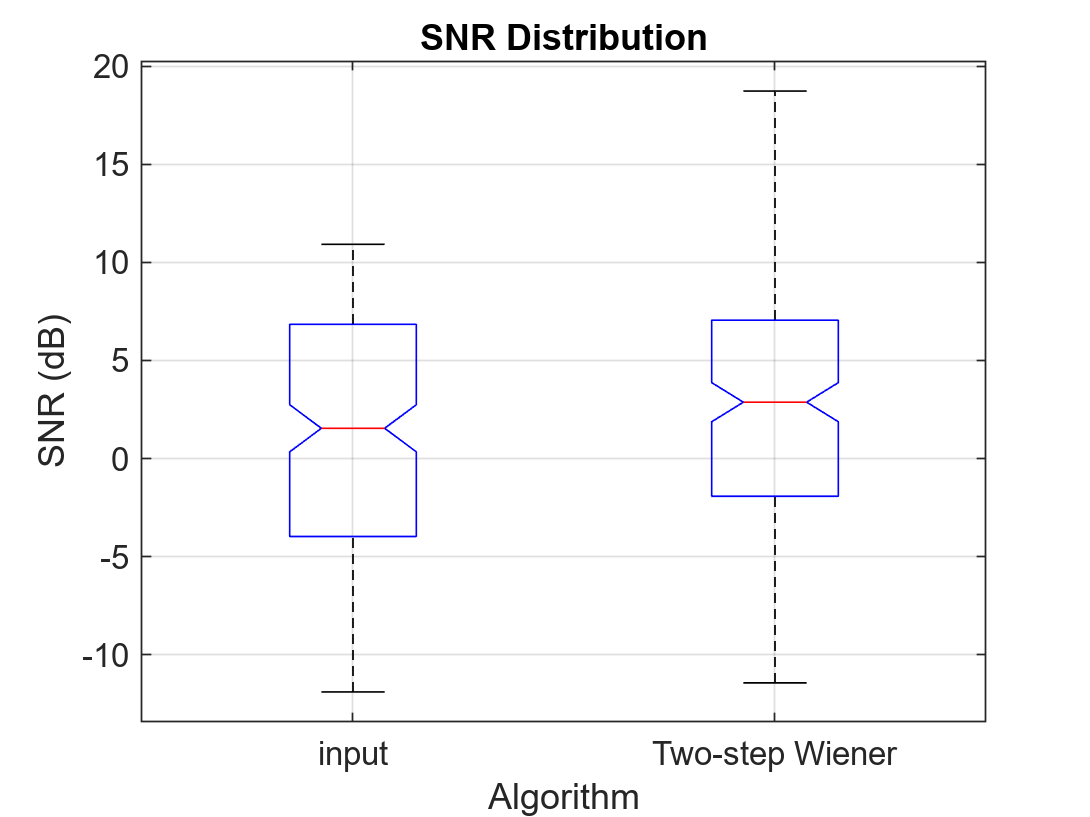

figure;
boxplot([initSnr, finalSnr], ...
    'Notch', 'on', ...
    'Labels', ["input", "Two-step Wiener"] ...
);
title("SNR Distribution");
xlabel("Algorithm");
ylabel("SNR (dB)");
grid;

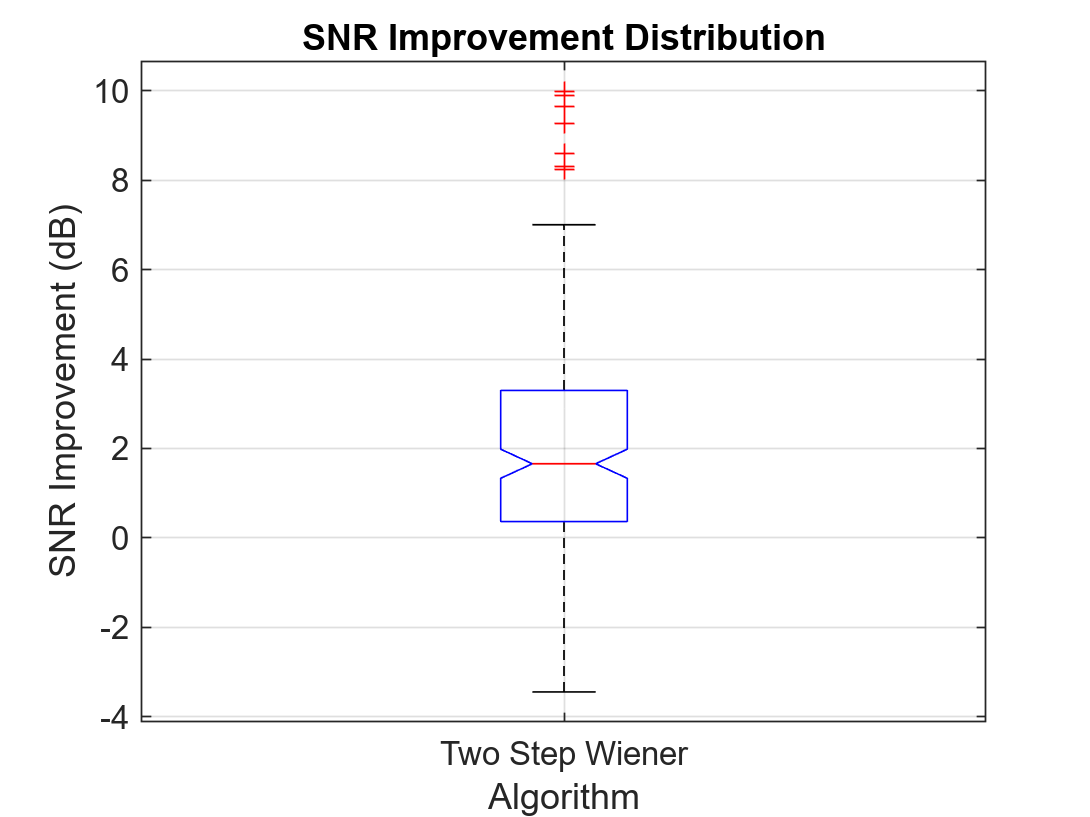


figure;
boxplot(deltaSnr, ...
    'Notch', 'on', ...
    'Labels', "Two Step Wiener" ...
);
title("SNR Improvement Distribution");
xlabel("Algorithm");
ylabel("SNR Improvement (dB)");
grid;

**Profiler**

profile clear

nProfileSamples = 14;

profile on
for i = 4:nProfileSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i, :), "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i, :), "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);
    
    estimSig = denoise(noisySig, fs);
end
profile off

p = profile('info');
profsave(p, "./doc/profile");

profile viewer;